clear
clc

% Initializing kero variables
KtL = 11.625; % Tank length in
KtD = 8; % Tank diameter in
KwM = (4.3*2.205) + 6.8711595; % Wet mass NO BULKHEADS lbm 
KdM = 6.8711595; % Dry mass NO BULKHEADS lbm
Kdensity = 820/27680; % Propellant density lbm/in^3 (820 kg/m^3)
Kmdot = (4.3*2.205)/10; % Mass flow rate lbm/s

% Initializing lox variables
LtL = 11.574; % Tank length in
LtD = 8; % Tank diameter in
LwM = (6.02*2.205) + 6.8407555; % Wet mass NO BULKHEADS lbm
LdM = 6.8407555; % Dry mass NO BULKHEADS lbm
Ldensity = 1148.5/27680; % Propellant density lbm/in^3 (1148.5 kg/m^3)
Lmdot = (6.02*2.205)/10; % Mass flow rate lbm/s

% Initializing n2 variables
NtL = 20.4; % Tank Length in
NtD = 6.7; % Tank Diameter in
NwM = 7.72 + (1.587834783*2.205); % Wet mass lbm
NdM = 7.72; % Dry mass lbm
Ndensity = 202.89/27680; % Propellant density lbm/in^3 (202.89 kg/m^3)
Nmdot = (1.587834783*2.205)/10; % Mass flow rate lbm/s

time = 10; % Burn time
burntime = linspace(0,time,11);


% Calling function
N2CoGs = getCoG(NwM, NdM, time, NtL, NtD, Ndensity, Nmdot);
T = array2table(N2CoGs,"VariableNames",{'Time (s)','Total Mass (g)','CoG (in from base of tank)','CoG (mm from top of tank)'});
T = table(T,'VariableNames',{'N2 CG'});
disp(T)

                                            N2 CG                                        
    Time (s)    Total Mass (g)    CoG (in from base of tank)    CoG (mm from top of tank)
    _____________________________________________________________________________________

        0           5089.8                  18.948                       36.868          
        1             4931                  18.439                       49.808          
        2           4772.2                  17.936                       62.585          
        3           4613.4                   17.44                       75.188          
        4           4454.6                  16.951                       87.608          
        5           4295.8                   16.47                       99.832          
        6             4137                  15.996                       111.85        

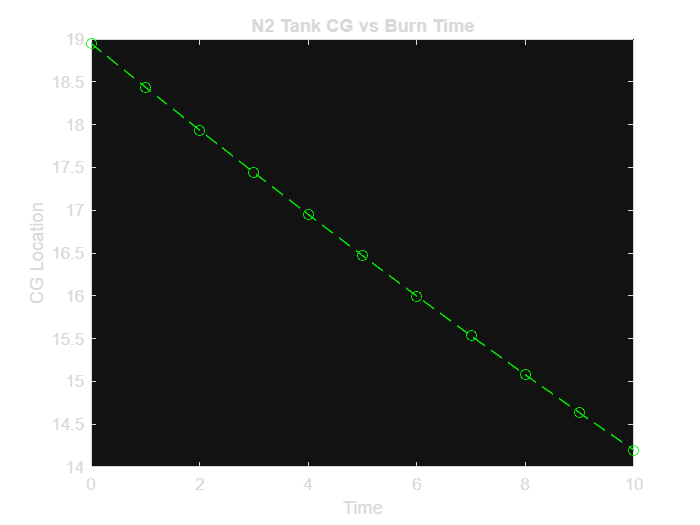

plot(burntime, N2CoGs(:,3),'g--o')
title("N2 Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')


KeroCoGs = getCoG(KwM, KdM, time, KtL, KtD, Kdensity, Kmdot);
T = array2table(KeroCoGs,"VariableNames",{'Time (s)','Total Mass (g)','CoG (in from base of tank)','CoG (mm from top of tank)'});
T = table(T,'VariableNames',{'Kero CG'});
disp(T)

                                           Kero CG                                       
    Time (s)    Total Mass (g)    CoG (in from base of tank)    CoG (mm from top of tank)
    _____________________________________________________________________________________

        0           7417.4                   6.166                       138.66          
        1           6987.4                  5.9395                       144.41          
        2           6557.3                  5.7212                       149.96          
        3           6127.2                  5.5122                       155.27          
        4           5697.1                  5.3138                        160.3          
        5           5267.1                  5.1278                       165.03          
        6             4837                  4.9561                       169.39        

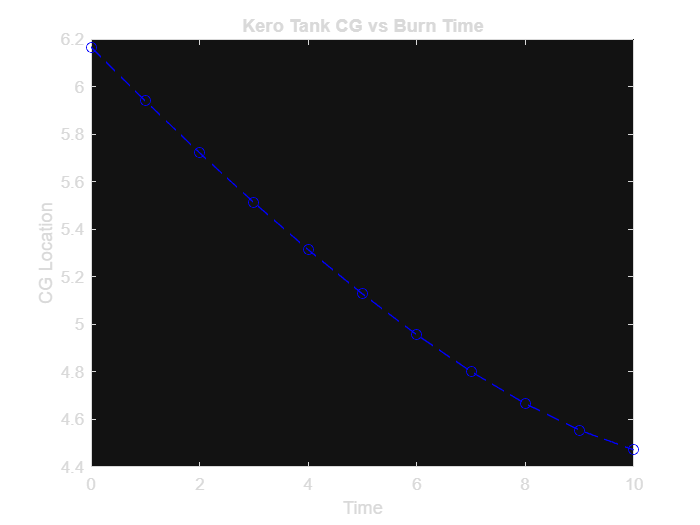

plot(burntime, KeroCoGs(:,3),'b--o')
title("Kero Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

LOXCoGs = getCoG(LwM, LdM, time, LtL, LtD, Ldensity, Lmdot);
T = array2table(LOXCoGs,"VariableNames",{'Time (s)','Total Mass (g)','CoG (in from base of tank)','CoG (mm from top of tank)'});
T = table(T,'VariableNames',{'LOX CG'});
disp(T)

                                           LOX CG                                        
    Time (s)    Total Mass (g)    CoG (in from base of tank)    CoG (mm from top of tank)
    _____________________________________________________________________________________

        0           9123.9                  5.6069                       151.56          
        1           8521.8                  5.3768                       157.41          
        2           7919.7                  5.1563                       163.01          
        3           7317.6                  4.9471                       168.32          
        4           6715.5                  4.7513                        173.3          
        5           6113.4                  4.5714                       177.87          
        6           5511.3                   4.411                       181.94        

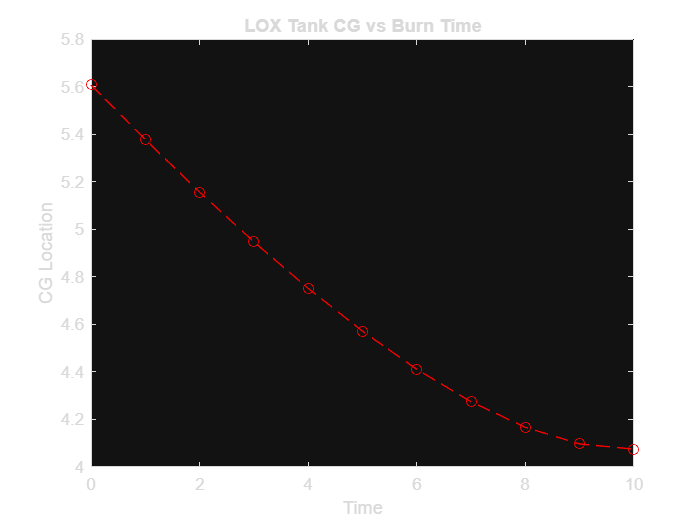

plot(burntime, LOXCoGs(:,3),'r--o')
title("LOX Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

function [CoGs] = getCoG(wM, dM, time, tL, tD, density, mdot)

Vo = (wM / density) * (1.15); % Finds initial propellant volume (1.15 term is for 15% ullage ratio)
tCG = dM * (tL/2); % Finds constant W1d1/tank term in COG equation
tR = tD / 2; % Converts tank diameter to radius

V = zeros(1,(round(time) + 1)); % Preallocates arrays for variables that change with time
mp = V;
d = V;
COG = V;
COGmm = V;
mpg = V;
% Done preallocating (for now), it's loop time yippee
for t = (0:time)
    mp(t+1) = wM - (mdot * t); % Finds propellant mass at t
    d(t+1) = ((Vo - ((mdot/density)*t)) / (2 * pi * ((tR) ^ 2))); % Finds the distance term for the propellant at t
    COG(t+1) = ((tCG + (mp(t+1) * d(t+1))) / (dM + mp(t+1))); % Finds (finally) the center of gravity at t
    COGmm(t+1) = (tL - COG(t+1)) * 25.4; % Converts CG value to mm from leading edge (needed in .rse file format)
    mpg(t+1) = mp(t+1) * 453.592; % Converts total mass to g (for .rse file creation)
end

CoGs = zeros((round(time) + 1),4); % Preallocates space for CoGs table
CoGs(:,1) = 0:(round(time)); % Makes column of time values
CoGs(:,2) = mpg; % Makes column of total mass values
CoGs(:,3) = COG; % Makes column of CoG values
CoGs(:,4) = COGmm; % Makes column of CoG values for rse files

end